**Question: How long will a flu outbreak in the future last?**

This predictive question is important for public health, individual, and economic reasons. For example, a hopsital would want to know when the outbreak knows so that it knows how to balance and budget their inventory. An individual may feel safer mentally and physically if they know when it ends. In addition, as we see with the coronavirus, these diseases can have economic reprecussions.

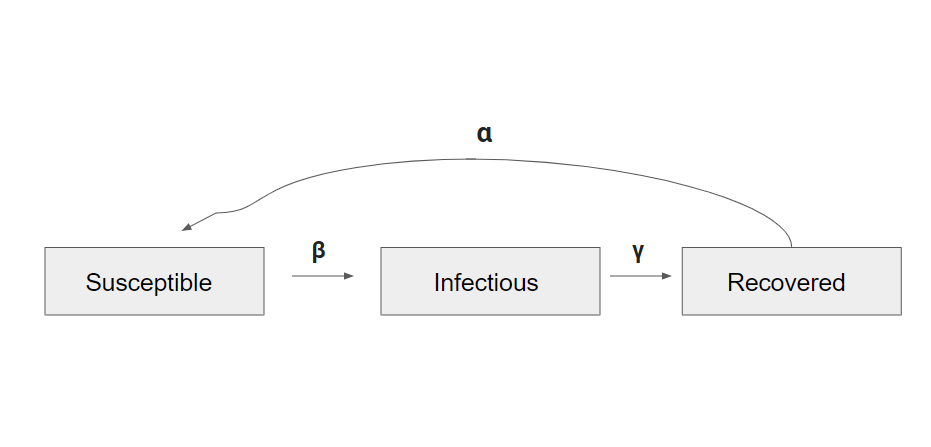

The equations listed below can help define our model. Listed below is also an explanation of the variables used in the equation


$$S_t = \text{Count of Susceptible persons at time } t \\
I_t = \text{Count of Infectious persons at time } t \\
R_t = \text{Count of Recovered persons at time } t $$



$$\Delta I_t = \text{Number of Infections at time } t \\
\Delta R_t = \text{Number of Recoveries at time } t\\
\Delta S_t = \text{Number of Resusceptiblities at time } t$$



$$S_{t+1} = S_t - \Delta I_t+\Delta S_t \\
I_{t+1} = I_t + \Delta I_t - \Delta R_t\\
R_{t+1} = R_t + \Delta R_t-\Delta S_t $$


In addition, $\Delta R_t = \gamma \times I_t$  , $\Delta I_t = \beta \times I_t \times S_t$ , and$\Delta S_t = \alpha \times R_t $.

**Assumptions**

In order to model this outbreak, we made a few assumptions. In the equation we made above to calcuate infection, recover, and resusceptibility, we assumed that these parameters are all dependent on the current amount of people in the different stocks.  For example, if there was only one person sick and a thousand people, then that one person would affect 1*1000*beta people. 

Furthermore, we assumed that everyone who is infected has the same ability to spread the virus as well as the same ability to recover. This may not reflect the real world where factors like age and other underlying conditions can negatively impact one's ability to recover. 

Along with assuming that everyone has the same ability to spread and recover from the virus, we also assumed that there were external factors that could change the rate of this virus. For example, changing seasons and mask wearing can affect the rate of the virus. 

**Defining Initial State**

First, we defined our initial state, and gave a guess of what suitable beta, gamma, and alpha values may be. These values were just placement holders, as we explore parameters and fit data latter on.


% Define initial state
% A population of 100 persons, 99 susceptible and 1 infectious
s_0 = 99;
i_0 = 1;
r_0 = 0;


% Infection rate: Each infected person has a chance to infect 1 susceptible
%                 person out of 50
% Recovery rate: The infection lasts 4 weeks before recovery
beta = 1 / 45;
gamma = 1/4;
alpha = 1/30;
num_week = 40;

**Running Our Simulation.**

Then, we ran our simulation for 40 weeks, and plotted the number of susceptible, infected, and recovered individuals per week.


% Run simulation
[S, I, R, W, w] = simulation(s_0, i_0, r_0, beta, gamma, alpha, num_week);

% Plot
figure(1); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})
%(s, i, r, beta, r_time, s_time, infected_list, step)
hold off;

**Fitting Our Data**

Next, we fitted our data by comparing our simulated graph to a past outbreak. We then changed parameters around, until our model fit. 

% Load the validation data
tab_data_wave2 = readtable("wave2.csv", "Delimiter", ",");
tab_data_validate = readtable("wave1.csv", "Delimiter", ",")

% Configure the simulation

s_0 = 99;
i_0 = 1;
r_0 = 0;
beta = 1 / 90;
gamma = 1/2;
alpha = 1/60;
num_week = 120;

% Run simulation
[S_fit, I_fit, R_fit, W, w] = simulation(s_0, i_0, r_0, beta, gamma, alpha, num_week);

% Plot the fitted simulation
figure(3); clf; hold on;

plot(W, I_fit, 'k-'); label1 = "Simulated";
plot(tab_data_validate.W, tab_data_validate.I, 'r:', 'LineWidth', 1.5); label2 = "Wave 1";
plot(tab_data_wave2.W, tab_data_wave2.I, 'g:', 'LineWidth', 2.0); label3 = "Wave 2";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2, label3})
title("Second Wave")


By playing around with the numbers, we found that the best fit was when beta = 1/90, gamma = 1/2,  and alpha = 1/60.

**Verification**

Next, we had to verify our model. To do this, we made sure that the total number of people would always equal one hundred. 

total = S_fit + I_fit + R_fit


[S_fit, I_fit, R_fit, W_fit, w] = simulation(s_0, i_0, r_0, beta, gamma, alpha, num_week);

% Plot the fitted simulation
figure(1); clf; hold on;
plot(W_fit, total, 'k-'); label2 = "Total Persons";

xlabel("Week")
ylabel("Total Persons")
legend({label1, label2})
title("Total Persons Over Time")

**Sweeping Parameters**

To visualize how our model changes, we swept all of the parameters involving the flow. We did this by keeping two parameters constant (consistent with our fitted data), and then plotting how infections changed with the other changing parameter. 

%run beta_sweep
beta_sweep(s_0, i_0, r_0, beta, gamma, alpha, num_week);
beta_sweep_end(s_0, i_0, r_0, beta, gamma, alpha, num_week);
alpha_sweep(s_0, i_0, r_0, beta, gamma, alpha, num_week);
gamma_sweep(s_0, i_0, r_0, beta, gamma, alpha, num_week);



**Results**

Next, we found out when the outbreak would end for our fitted data. To do this, we defined the end of the outbreak as when the slope first equaled around zero (less than one), excluding the peak. 

s_0 = 99;
i_0 = 1;
r_0 = 0;
beta = 1 / 90;
gamma = 1/2;
alpha = 1/60;
num_week = 120;

% Run simulation
[S_fit, I_fit, R_fit, W, w] = simulation(s_0, i_0, r_0, beta, gamma, alpha, num_week);


[w] = end_check(I_fit);
end_I = I_fit(w);

% Plot the fitted simulation
figure(3); clf; hold on;

plot(W, I_fit, 'k-'); label1 = "Simulated";
plot(w,end_I,'ro'); label2 = "outbreak_ end"

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2})
title("When Does Outbreak End")

end_text = 'outbreak ends at week'
disp(end_text)
disp(w)


From our results, we can conclude that based on our fitted data, the outbreak ends at week 20. 

**Comparison**

If we change how infectious the disease is we see how our results would change. 

beta_sweep_end(s_0, i_0, r_0, beta, gamma, alpha, num_week)
gamma_sweep_end(s_0, i_0, r_0, beta, gamma, alpha, num_week)
alpha_sweep_end(s_0, i_0, r_0, beta, gamma, alpha, num_week)

**Results**

From our results, we can conclude that based on our fitted data, the outbreak in its first wave ends at week 20. However, based on our model under the fitted parameters, subsequent waves seem to periodically repeat. However, by sweeping the endpoints of the outbreak based on infection, recovery, and resusceptibility rates, we can determine that the ending of an outbreak is highly variable and dependent on the model being well fitted for its purpose.

**Interpretation**

Although fairly simple, our model follows the validation data very well once fitted. Qualitatively, the validation outbreak seems to end at about week 20, our calculated result. However, if we were given only the limited information of infections at the start of an outbreak, the high variance of the outbreak end based on the parameters indicates that we would struggle to properly fit our model, and therefore our outbreak end result would likely be very innacurite

Our code to calculate the end of the outbreak places the bar somewhat arbitrarily at 1 infection per week, and because it is not proportional to the size of the population, this probably does not work with larger populations. Furthermore, the model only calculates the first outbreak ending and does not account for further waves.

If we were going to continue developing our model, we may want to be able to calculate when other waves end. In addition, we would validate our model. As of right now, we only have it fitted to one data set. In order to validate it, we would need to test our simulated model against different data. 